# a) No equilibrium: (ode45 version)

#  
$$^{138}Xe-^{138}Cs$$


clc,clearvars,clf

%half lives,minute
tHalfP=14.18; 
tHalfD=33.41;  
%decay constants
lambdaP=log(2)/tHalfP; 
lambdaD=log(2)/tHalfD;
%Bateman equations
Bateman=@(t,N)[(-lambdaP*N(1));(lambdaP*N(1)-lambdaD*N(2))];
%using ode45 for numerical solution of Bateman equations
[t,N]=ode45(Bateman,[0 200],[1/lambdaP 0]);
%activity 
AP=lambdaP*N(:,1); 
AD=lambdaD*N(:,2); 

#### Plotting activity vs. time graph

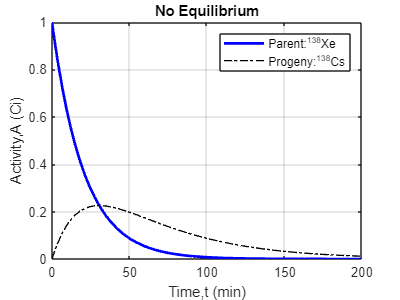

%parent activity vs. time graph
plot(t,AP,'b','linewidth',2) 
hold on
%progeny activity vs. time graph
plot(t,AD,'k-.','linewidth',1) 
xlabel('Time,t (min)')
ylabel('Activity,A (Ci)')
legend('Parent:^{138}Xe','Progeny:^{138}Cs')
title('No Equilibrium')
grid on